# BIKE Equations of Motion Derivation

## Step 1: Set up all of the state variables and symbols

Currently we will track 5 states of our robot. 

- x position of the body

- y position of the body

- anlge of the body COM

- angle of the back wheel

- angle of the front wheel

Then using known parameters from our CAD model we can full define a set of transformations that represent the state of these variables.

% x_bf: position of the backwheel along the x-axis
% y_bf: position of the backwheel along the y-axis
% theta_com: angle of the bike orientation, ccw+ w.r.t. x-axis
% theta_bw: angle of the backwheel, ccw+ w.r.t. x-axis
% theta_fw: angle of the frontwheel, ccw+ w.r.t. x-axis
syms x_bf y_bf theta_com theta_bw theta_fw real

% q: state-variables
q = [x_bf; y_bf; theta_com; theta_bw; theta_fw];

% Generalized velocities: 
% dq: first derivative of state variables w.r.t time
syms dx_bf dy_bf dtheta_com dtheta_bw dtheta_fw real
dq = [dx_bf; dy_bf; dtheta_com; dtheta_bw; dtheta_fw];

% Generalized accelerations: 
% ddq: second derivative of state variables w.r.t time
syms ddx_bf ddy_bf ddtheta_com ddtheta_bw ddtheta_fw real
ddq = [ddx_bf; ddy_bf; ddtheta_com; ddtheta_bw; ddtheta_fw];

% compute derivatives using chain-rule
derivative = @(in)( jacobian(in,[q;dq])*[dq;ddq] )

derivative = function_handle with value:
    @(in)(jacobian(in,[q;dq])*[dq;ddq])



dx_bf = derivative(x_bf);
dy_bf = derivative(y_bf);
dtheta_com = derivative(theta_com);
dtheta_bw = derivative(theta_bw);
dtheta_fw = derivative(theta_fw);

ddx_bf = derivative(dx_bf);
ddy_bf = derivative(dy_bf);
ddtheta_com = derivative(dtheta_com);
ddtheta_bw = derivative(dtheta_bw);
ddtheta_fw = derivative(dtheta_fw);

% Mass:
syms m_com real % mass of bike
syms m_bw real  % mass of backwheel
syms m_fw real  % mass of frontwheel

% Position:
syms bw_com_distance real %straight line distance between backwheel and CoM
syms bw_com_init_angle real %Initial angle between backwheel and CoM

syms bw_fw_distance real %The distance between the two wheels

syms x_bw real  % x_position of backwheel relative to CoM
syms y_bw real  % y_position of frontwheel relative to CoM
syms x_fw real  % x_position of frontwheel relative to CoM
syms y_fw real  % y_position of frontwheel relative to CoM

% Dimension:
syms r_bw real;
syms r_fw real;

% Moment of Inertia
syms I_fw real  % MoI of frontwheel
syms I_bw real  % MoI of backwheel
syms I_com real % Moi of bike

g = sym('g','real'); % gravity
t = sym('t','real'); % time

## Step 2: Set up the transformations 

The key component here is to know where each body of the bike is relative to a world frame.

The key parameters we need to draw from CAD are:

- Distance and angle between the back wheel and COM

- Distance and angle between the front wheel and COM (currently we are not modeling the spring assembly)

#### Key Frames

Base Frame (bf): located at the center of the back wheel, but the orientation remains fixed to the center of the wheel

Back Wheel (bw): located at the center of the back wheet, but also rotates to match the amount the back wheel has rotated.

COM (com): located at the center of mass oriented inline with the fixed angle based on the back wheel. From here this frame will also rotate as the bike rotates.

Front Wheel (fw): located at the center of the front wheel and also rotates to match the amount the front wheel has rotated.

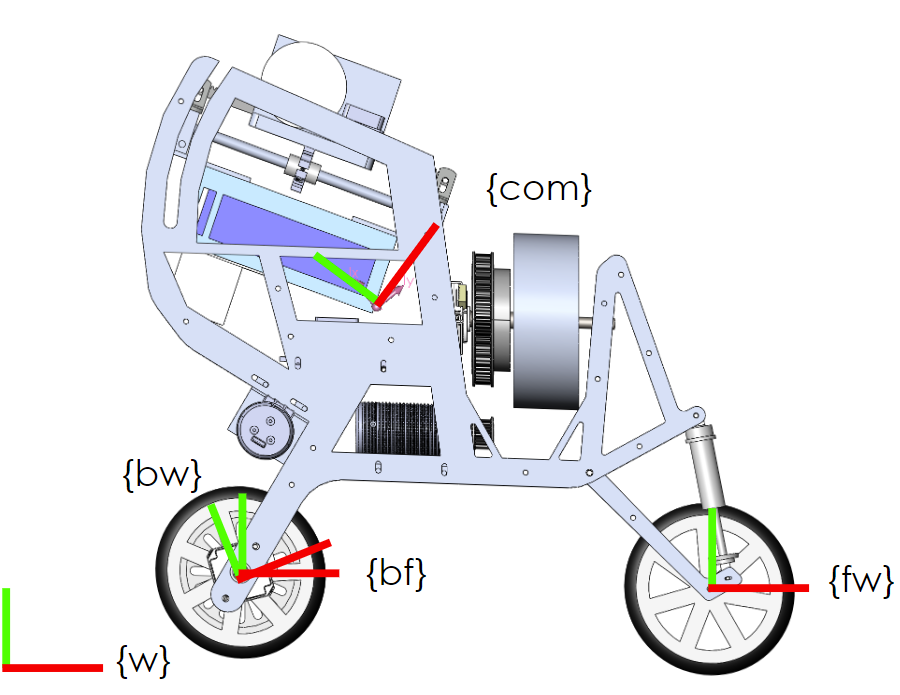

% Base Frame -> Back Wheel
% The base frame is located at the center of the back wheel
g_bf_bw = [[cos(theta_bw), -sin(theta_bw), 0]; 
           [sin(theta_bw), cos(theta_bw), 0];
           [0, 0, 1]];

% Base Frame -> COM
% First rotate to the angle of the COM which is the fixed initial angle
% plus the additional rotation
% Then Translate based on a fixed distance to the COM
g_rot = [[cos(bw_com_init_angle + theta_com), -sin(bw_com_init_angle + theta_com), 0]; 
            [sin(bw_com_init_angle + theta_com), cos(bw_com_init_angle + theta_com), 0];
            [0, 0, 1]];

g_trans = [[1, 0, bw_com_distance]; 
           [0, 1, 0];
           [0, 0, 1]];

g_bf_com = g_rot * g_trans;

% Base Frame -> Front Wheel
% First rotate by the amount the bike has rotated, then translate by the
% distance between the wheels

g_rot_com = [[cos(theta_com), -sin(theta_com), 0]; 
         [sin(theta_com), cos(theta_com), 0];
         [0, 0, 1]];
     
g_trans = [[1, 0, bw_fw_distance]; 
           [0, 1, 0];
           [0, 0, 1]];

g_rot_com_rev = [[cos(-theta_com), -sin(-theta_com), 0]; 
         [sin(-theta_com), cos(-theta_com), 0];
         [0, 0, 1]];
       
g_rot_fw = [[cos(theta_fw), -sin(theta_fw), 0]; 
            [sin(theta_fw), cos(theta_fw), 0];
            [0, 0, 1]];
        
g_bf_fw = g_rot_com*g_trans*g_rot_com_rev*g_rot_fw;


Our Final Set of Transforms relative to the World frame are:

% Coordiantes transformation matrices:
% World -> Base Frame
g_wbf = [[cos(0), -sin(0), x_bf]; 
          [sin(0), cos(0), y_bf];
          [0, 0, 1]]

$$g\_wbf = \left(\begin{array}{ccc} 1 & 0 & x_{\mathrm{bf}}\\ 0 & 1 & y_{\mathrm{bf}}\\ 0 & 0 & 1 \end{array}\right)$$


% World -> Backwheel
g_wbw = simplify(g_wbf * g_bf_bw)

$$g\_wbw = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{bw}}\right) & -\sin\left(\theta_{\mathrm{bw}}\right) & x_{\mathrm{bf}}\\ \sin\left(\theta_{\mathrm{bw}}\right) & \cos\left(\theta_{\mathrm{bw}}\right) & y_{\mathrm{bf}}\\ 0 & 0 & 1 \end{array}\right)$$

      
% World -> COM
g_wcom = simplify(g_wbf*g_bf_com)

$$g\_wcom = \left(\begin{array}{ccc} \cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right) & -\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right) & x_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\\ \sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right) & \cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right) & y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\\ 0 & 0 & 1 \end{array}\right)$$


% World -> Frontwheel
g_wfw = simplify(g_wbf*g_bf_fw)

$$g\_wfw = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{fw}}\right) & -\sin\left(\theta_{\mathrm{fw}}\right) & x_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\cos\left(\theta_{\mathrm{com}}\right)\\ \sin\left(\theta_{\mathrm{fw}}\right) & \cos\left(\theta_{\mathrm{fw}}\right) & y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\sin\left(\theta_{\mathrm{com}}\right)\\ 0 & 0 & 1 \end{array}\right)$$

## Step 3: Compute the Kinetic Energies

This can be done very formulaically now that we have fully defined our transformations relative to the world. 

The twist of each body can be calculated using the previously defined transformations. This will then be converted into a 3-vector that will capture our linear and angular velocities. We have defined this as a column [vx; vy; wz]

We also need to define our Spatial Inertia matricies that will be multiplied with our twist vector. 

% Mass matrices
G_com = [[m_com, 0, 0]; % bike CoM
         [0, m_com, 0]; 
         [0, 0, I_com]];

G_bw = [[m_bw, 0, 0];  % backwheel
        [0, m_bw, 0];
        [0, 0, I_bw]];

G_fw = [[m_fw, 0, 0];  % frontwheel
        [0, m_fw, 0];
        [0, 0, I_fw]];

%Note: to apply derivative(), convert matrices into column vectors
vector_g_wcom = g_wcom(:);
vector_g_wbw = g_wbw(:);
vector_g_wfw = g_wfw(:);

g_row = sqrt(numel(g_wbw));
g_column = sqrt(numel(g_wbw));
g_size = [g_column, g_row];

diff_g_wcom = reshape(derivative(vector_g_wcom), g_size); %d(g_wcom)/dt
diff_g_wbw = reshape(derivative(vector_g_wbw), g_size); %d(g_wb)/dt
diff_g_wfw = reshape(derivative(vector_g_wfw), g_size); %d(g_wf)/dt

% Velocity vectors(hat):
V_com = TransInv(g_wcom)*diff_g_wcom;
unhat_V_com = simplify([V_com(1,3); V_com(2,3); V_com(2,1)])

$$unhat\_V\_com = \left(\begin{array}{c} {\mathrm{dx}}_{\mathrm{bf}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)+{\mathrm{dy}}_{\mathrm{bf}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\\ {\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}+{\mathrm{dy}}_{\mathrm{bf}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)-{\mathrm{dx}}_{\mathrm{bf}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\\ {\mathrm{dtheta}}_{\mathrm{com}} \end{array}\right)$$


V_bw = TransInv(g_wbw)*diff_g_wbw;  
unhat_V_bw = simplify([V_bw(1,3); V_bw(2,3); V_bw(2,1)])

$$unhat\_V\_bw = \left(\begin{array}{c} {\mathrm{dx}}_{\mathrm{bf}}\,\cos\left(\theta_{\mathrm{bw}}\right)+{\mathrm{dy}}_{\mathrm{bf}}\,\sin\left(\theta_{\mathrm{bw}}\right)\\ {\mathrm{dy}}_{\mathrm{bf}}\,\cos\left(\theta_{\mathrm{bw}}\right)-{\mathrm{dx}}_{\mathrm{bf}}\,\sin\left(\theta_{\mathrm{bw}}\right)\\ {\mathrm{dtheta}}_{\mathrm{bw}} \end{array}\right)$$


V_fw = TransInv(g_wfw)*diff_g_wfw; 
unhat_V_fw = simplify([V_fw(1,3); V_fw(2,3); V_fw(2,1)])

$$unhat\_V\_fw = \left(\begin{array}{c} {\mathrm{dx}}_{\mathrm{bf}}\,\cos\left(\theta_{\mathrm{fw}}\right)+{\mathrm{dy}}_{\mathrm{bf}}\,\sin\left(\theta_{\mathrm{fw}}\right)+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{fw}}-\theta_{\mathrm{com}}\right)\\ {\mathrm{dy}}_{\mathrm{bf}}\,\cos\left(\theta_{\mathrm{fw}}\right)-{\mathrm{dx}}_{\mathrm{bf}}\,\sin\left(\theta_{\mathrm{fw}}\right)+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{fw}}-\theta_{\mathrm{com}}\right)\\ {\mathrm{dtheta}}_{\mathrm{fw}} \end{array}\right)$$


% Kinetic Energy: 
KE_com = simplify(0.5*transpose(unhat_V_com)*G_com*unhat_V_com);
KE_bw = simplify(0.5*transpose(unhat_V_bw)*G_bw*unhat_V_bw);
KE_fw = simplify(0.5*transpose(unhat_V_fw)*G_fw*unhat_V_fw);

% total kinetic energy
KE = simplify(KE_com + KE_bw + KE_fw) 

$$KE = \frac{I_{\mathrm{bw}}\,{{\mathrm{dtheta}}_{\mathrm{bw}}}^{2}}{2}+\frac{I_{\mathrm{com}}\,{{\mathrm{dtheta}}_{\mathrm{com}}}^{2}}{2}+\frac{I_{\mathrm{fw}}\,{{\mathrm{dtheta}}_{\mathrm{fw}}}^{2}}{2}+\frac{{{\mathrm{dx}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{bw}}}{2}+\frac{{{\mathrm{dx}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{com}}}{2}+\frac{{{\mathrm{dx}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{fw}}}{2}+\frac{{{\mathrm{dy}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{bw}}}{2}+\frac{{{\mathrm{dy}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{com}}}{2}+\frac{{{\mathrm{dy}}_{\mathrm{bf}}}^{2}\,m_{\mathrm{fw}}}{2}+\frac{{{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}}^{2}\,{{\mathrm{dtheta}}_{\mathrm{com}}}^{2}\,m_{\mathrm{com}}}{2}+\frac{{{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}}^{2}\,{{\mathrm{dtheta}}_{\mathrm{com}}}^{2}\,m_{\mathrm{fw}}}{2}+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dy}}_{\mathrm{bf}}\,m_{\mathrm{com}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dx}}_{\mathrm{bf}}\,m_{\mathrm{com}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dy}}_{\mathrm{bf}}\,m_{\mathrm{fw}}\,\cos\left(\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dx}}_{\mathrm{bf}}\,m_{\mathrm{fw}}\,\sin\left(\theta_{\mathrm{com}}\right)$$

## Step 4: Calculate the Potential Energy

Since our bike is not just meant to drive on a flat ground, we need to consider the potential energy of each component. This is just PE = mgh for each body.

% Potential Energy: 
PE_com = m_com * g * g_wcom(2,3)

$$PE\_com = g\,m_{\mathrm{com}}\,\left(y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\right)$$

PE_bw = m_bw * g * g_wbw(2,3)    

$$PE\_bw = g\,m_{\mathrm{bw}}\,y_{\mathrm{bf}}$$

PE_fw = m_fw * g * g_wfw(2,3)    

$$PE\_fw = g\,m_{\mathrm{fw}}\,\left(y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\sin\left(\theta_{\mathrm{com}}\right)\right)$$


% total potential energy
PE = simplify(PE_com + PE_bw + PE_fw)

$$PE = g\,m_{\mathrm{com}}\,\left(y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\right)+g\,m_{\mathrm{bw}}\,y_{\mathrm{bf}}+g\,m_{\mathrm{fw}}\,\left(y_{\mathrm{bf}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\sin\left(\theta_{\mathrm{com}}\right)\right)$$

## Step 5: Caclulate the LHS of the EL Equations

Now that we have the Kinetic and Potential Energies, we can get the Legrangian and find the Euler Legrange Equations for the bike.

% Euler-Langrangian Equation
L = KE - PE; 

%Deriving Euler Lagragian equations
del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d/dt(del L/del dq)
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_qdot = jacobian(KE,dq)';
ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;dq])*[dq;ddq])

ELeq_term2 = simplify(jacobian((KE-PE),q))'

$$ELeq\_term2 = \left(\begin{array}{c} 0\\ -g\,\left(m_{\mathrm{bw}}+m_{\mathrm{com}}+m_{\mathrm{fw}}\right)\\ -{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,g\,m_{\mathrm{com}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,g\,m_{\mathrm{fw}}\,\cos\left(\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dx}}_{\mathrm{bf}}\,m_{\mathrm{com}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dy}}_{\mathrm{bf}}\,m_{\mathrm{com}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dx}}_{\mathrm{bf}}\,m_{\mathrm{fw}}\,\cos\left(\theta_{\mathrm{com}}\right)-{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,{\mathrm{dy}}_{\mathrm{bf}}\,m_{\mathrm{fw}}\,\sin\left(\theta_{\mathrm{com}}\right)\\ 0\\ 0 \end{array}\right)$$

## Step 6: Build the Constraints

Now to make our bike behave like a real bike. We need to apply the following constraints:

- The bike translates horizontally based on the rotation of the back wheel.

- The centers of each wheel stay a fixed distance away from the ground plane. (Currently this is just a flat plane)

These are then passed to respective functions so we can analyze the Reaction Forces and properly incorperate them into the final Equations of Motion.

% Constraints
Con = sym('Con',[numel(q), 1],'real'); %constraint matrix

% Constraint so that the back wheel effects the x position of the COM
c_bw_x = x_bf + theta_bw*r_bw

$$c\_bw\_x = x_{\mathrm{bf}}+r_{\mathrm{bw}}\,\theta_{\mathrm{bw}}$$

% Constrains so the back wheel does not fall through the floor
%c_fw_x = x_com - theta_bw*r_bw - x_fw;
c_bw_y = g_wbw(2,3) - r_bw

$$c\_bw\_y = y_{\mathrm{bf}}-r_{\mathrm{bw}}$$

% Constrains so the front wheel does not fall through the floor
c_fw_y = g_wfw(2,3) - r_bw

$$c\_fw\_y = y_{\mathrm{bf}}-r_{\mathrm{bw}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\sin\left(\theta_{\mathrm{com}}\right)$$

% Constrains so the front wheel and back wheel spin with the same velocity
c_fw_bw = theta_bw*r_bw - theta_fw*r_fw

$$c\_fw\_bw = r_{\mathrm{bw}}\,\theta_{\mathrm{bw}}-r_{\mathrm{fw}}\,\theta_{\mathrm{fw}}$$


syms r_ramp real; %radius of the ramp
syms x_ramp y_ramp real; %center of the ramp

% Constrains so the backwheel is on the ramp
c_bw_ramp = (g_wbw(1,3)-x_ramp)^2 + (g_wbw(2,3)-y_ramp)^2 -r_ramp^2

$$c\_bw\_ramp = {\left(x_{\mathrm{bf}}-x_{\mathrm{ramp}}\right)}^{2}+{\left(y_{\mathrm{bf}}-y_{\mathrm{ramp}}\right)}^{2}-{r_{\mathrm{ramp}}}^{2}$$

% Constrains so the frontwheel is on the ramp
c_fw_ramp = (g_wfw(1,3)-x_ramp)^2 + (g_wfw(2,3)-y_ramp)^2 -r_ramp^2

$$c\_fw\_ramp = {\left(x_{\mathrm{bf}}-x_{\mathrm{ramp}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\cos\left(\theta_{\mathrm{com}}\right)\right)}^{2}+{\left(y_{\mathrm{bf}}-y_{\mathrm{ramp}}+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,\sin\left(\theta_{\mathrm{com}}\right)\right)}^{2}-{r_{\mathrm{ramp}}}^{2}$$


C_all = [c_bw_x;c_bw_y;c_fw_y;c_fw_bw;c_bw_ramp;c_fw_ramp];

matlabFunction(C_all,'File','autogen_constraints');

% A-matrix and H:
A_all = jacobian(C_all, q); %A-matrix for constraint
H_bw_x = hessian(c_bw_x, q); 
H_bw_y = hessian(c_bw_y, q); 
H_fw_y = hessian(c_fw_y, q); 
H_fw_bw = hessian(c_fw_bw, q); 
H_bw_ramp = hessian(c_bw_ramp, q);
H_fw_ramp = hessian(c_fw_ramp, q);

matlabFunction(A_all,H_bw_x,H_bw_y,H_fw_y,H_fw_bw,H_bw_ramp,H_fw_ramp,'File','autogen_constraint_derivatives');


## Step 7: Define the External Forces

These are all of the forces that will act on the bike

- Back motor torque applied to the back wheel

Q = sym('Q', [numel(q),1],'real');
syms tau_bw real;

Q = [0;0;0;tau_bw;0]; 

## Step 8: Caclulate our M, C, and G

These are the last components needed to solve for our equations of motion.

%Computing Mass Matrix
M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');


M = simplify(jacobian(del_L_del_qdot,dq));
H = simplify(jacobian(del_L_del_qdot,q)*dq - ELeq_term2)

$$H = \left(\begin{array}{c} -{{\mathrm{dtheta}}_{\mathrm{com}}}^{2}\,\left({\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,m_{\mathrm{fw}}\,\cos\left(\theta_{\mathrm{com}}\right)+{\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,m_{\mathrm{com}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)\right)\\ g\,\left(m_{\mathrm{bw}}+m_{\mathrm{com}}+m_{\mathrm{fw}}\right)-{\mathrm{dtheta}}_{\mathrm{com}}\,\left({\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,m_{\mathrm{com}}\,\sin\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,{\mathrm{dtheta}}_{\mathrm{com}}\,m_{\mathrm{fw}}\,\sin\left(\theta_{\mathrm{com}}\right)\right)\\ {\mathrm{bw}}_{\mathrm{com},\mathrm{distance}}\,g\,m_{\mathrm{com}}\,\cos\left({\mathrm{bw}}_{\mathrm{com},\mathrm{init},\mathrm{angle}}+\theta_{\mathrm{com}}\right)+{\mathrm{bw}}_{\mathrm{fw},\mathrm{distance}}\,g\,m_{\mathrm{fw}}\,\cos\left(\theta_{\mathrm{com}}\right)\\ 0\\ 0 \end{array}\right)$$


Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M))


matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H_eom');
fprintf("Done Deriving Equations!")

Done Deriving Equations!

### CUSTOM FUNCTIONS

function g_inv = TransInv(g)
    
    g_inv = g;
    
    % Extract the rotation component
    R = g(1:2,1:2);
    R_T = R';
    % Extract the Translation Component
    p = g(1:2, 3);
    p_T = - R_T * p;
    
    
    g_inv(1:2,1:2) = R_T;
    g_inv(1:2, 3) = p_T;
end